% analyze neural model data

% create the matrices from neural model
nswimbouts_fs = size(nc_fs,1);
nswimbouts_er = size(nc_er,1);
nc_fs_neuro = cell(nswimbouts_fs,1);
nc_er_neuro = cell(nswimbouts_er,1);
nframes_fs = zeros(nswimbouts_fs,1);
nframes_er = zeros(nswimbouts_er,1);
swimbouts_fs_n = zeros(nswimbouts_fs,4);
swimbouts_er_n = zeros(nswimbouts_er,5);

% original swimming bouts
ang_fs_o = cell2mat(nc_fs(:,2));
ang_er_o = cell2mat(nc_er(:,2));
ang_fs_o(:,2) = [];
ang_er_o(:,2) = [];


% neural model swimming bouts
for n = 1:nswimbouts_fs
    swimboutmat = nc_fs{n,2};
    x = nc_fs_result{n,1};
    ns = length(x)/3;
    a1 = x(1:ns/2)/10;
    a2 = x(ns/2+1:ns)/10;
    B2 = cumsum(x(ns+1:ns*2));
    B1 = B2 + x(ns*2+1:ns*3);
    nframes = size(swimboutmat,1);
    nframes_fs(n,1) = nframes;
    neuromat = gen_neuromodel(B1,B2,a1,a2,nframes);
    t = -neuromat';
    t = t(1:nframes,:);
    t(:,2) = [];
    nc_fs_neuro{n,1} = t;
end

for n = 1:nswimbouts_er
    swimboutmat = nc_er{n,2};
    x = nc_er_result{n,1};
    ns = length(x)/3;
    a1 = x(1:ns/2)/10;
    a2 = x(ns/2+1:ns)/10;
    B2 = cumsum(x(ns+1:ns*2));
    B1 = B2 + x(ns*2+1:ns*3);
    nframes = size(swimboutmat,1);
    nframes_er(n,1) = nframes;
    neuromat = gen_neuromodel(B1,B2,a1,a2,nframes);
    t = -neuromat';
    t = t(1:nframes,:);
    t(:,2) = [];
    nc_er_neuro{n,1} = t;
end

ang_fs_n = cell2mat(nc_fs_neuro);
ang_er_n = cell2mat(nc_er_neuro);
ang_neuro = [ang_er_n;ang_fs_n];
ang_original = [ang_er_o;ang_fs_o];
ang_all = [ang_neuro;ang_original];



for n = 1:nswimbouts_fs
    swimbouts_fs_n(n,1:2) = swimbouts_fs(nc_fs{n,1},1:2);
    if n == 1
        swimbouts_fs_n(n,3:4) = [1,nframes_fs(n,1)];
    else
        swimbouts_fs_n(n,3:4) = [swimbouts_fs_n(n-1,4)+1, swimbouts_fs_n(n-1,4)+nframes_fs(n,1)];
    end
end

for n = 1:nswimbouts_er
    swimbouts_er_n(n,1:2) = swimbouts_er(nc_er{n,1},1:2);
    swimbouts_er_n(n,5) = swimbouts_er(nc_er{n,1},5);
    if n == 1
        swimbouts_er_n(n,3:4) = [1,nframes_er(n,1)];
    else
        swimbouts_er_n(n,3:4) = [swimbouts_er_n(n-1,4)+1, swimbouts_er_n(n-1,4)+nframes_er(n,1)];
    end
end

% SVD
[un,sn,vn] = svd(ang_neuro,0);
[uo,so,vo] = svd(ang_original,0);
[u,s,v] = svd(ang_all,0);

% neural model
uc_er = cell(nswimbouts_er,1);
for n = 1:nswimbouts_er
    startFrame = swimbouts_er_n(n,3);
    endFrame = swimbouts_er_n(n,4);
    uc_er{n} = un(startFrame:endFrame , :);
    peak1 = find(abs(uc_er{n})>0.001,1);
    if uc_er{n}(peak1) < 0
        uc_er{n} = -uc_er{n};
    end
end

nframes_er = swimbouts_er_n(end,4);
uc_fs = cell(nswimbouts_fs,1);
for n = 1:nswimbouts_fs
    startFrame = swimbouts_fs_n(n,3)+nframes_er;
    endFrame = swimbouts_fs_n(n,4)+nframes_er;
    uc_fs{n} = un(startFrame:endFrame , :);
    peak1 = find(abs(uc_fs{n})>0.001,1);
    if uc_fs{n}(peak1) < 0
        uc_fs{n} = -uc_fs{n};
    end
end


% original movies
uc_er_o = cell(nswimbouts_er,1);
for n = 1:nswimbouts_er
    startFrame = swimbouts_er_n(n,3);
    endFrame = swimbouts_er_n(n,4);
    uc_er_o{n} = uo(startFrame:endFrame , :);
    peak1 = find(abs(uc_er_o{n})>0.001,1);
    if uc_er_o{n}(peak1) < 0
        uc_er_o{n} = -uc_er_o{n};
    end
end

nframes_er = swimbouts_er_n(end,4);
uc_fs_o = cell(nswimbouts_fs,1);
for n = 1:nswimbouts_fs
    startFrame = swimbouts_fs_n(n,3)+nframes_er;
    endFrame = swimbouts_fs_n(n,4)+nframes_er;
    uc_fs_o{n} = uo(startFrame:endFrame , :);    
    peak1 = find(abs(uc_fs_o{n})>0.001,1);
    if uc_fs_o{n}(peak1) < 0
        uc_fs_o{n} = -uc_fs_o{n};
    end
end



%% find first 2 cycles 
% get rid of fs swimming bouts without 2 peaks
badswimbouts = [];
ct = 0;
thresh = 0.001;
uc_fs_1 = cell(1,1);
for n = 1:length(uc_fs)
    u1 = uc_fs{n}(:,1);
    u2 = uc_fs{n}(:,2);
    u3 = uc_fs{n}(:,3);
    % v stands for valley, p stands for peak
    peakloc_v = peakfinder(-u1,thresh); % find the peak in u1 at two minimas
    p_fs{n,1} = peakloc_v;
    if length(peakloc_v) > 1
        peakloc_p = peakfinder(u1(peakloc_v(1):end),thresh) + peakloc_v(1) - 1;
        p_fs{n,2} = peakloc_p;
        if length(peakloc_p) > 1
            peak1 = peakloc_v(1);
            ct = ct+1;
            if u1(peak1) > 0
                ul = -u1;
                u2 = -u2;
                u3 = -u3;
            end
            uc_fs_1{ct,1} = [u1(1:peakloc_p(1)),u2(1:peakloc_p(1)),u3(1:peakloc_p(1))];
        else
            badswimbouts = [n,badswimbouts];
        end
    else
        badswimbouts = [n,badswimbouts];
    end
end
nbadswimbouts = length(badswimbouts);
for n = 1:nbadswimbouts
    m = badswimbouts(n);
    swimbouts_fs(m+1:end,3:4) = swimbouts_fs(m+1:end,3:4)-(swimbouts_fs(m,4)-swimbouts_fs(m,3)+1);
    ang_mf_fs(swimbouts_fs(m,3):swimbouts_fs(m,4),:) = [];
    coor_mf_fs(:,:,swimbouts_fs(m,3):swimbouts_fs(m,4)) = [];
    swimbouts_fs(m,:) = [];
    uc_fs(m) = [];
end


% get rid of er swimming bouts without 2 peaks
badswimbouts = [];
ct = 0;
thresh = 0.002;
uc_er_1 = cell(1,1);
for n = 1:length(uc_er)
    u1 = smooth(uc_er{n}(:,1),5);
    u2 = smooth(uc_er{n}(:,2),5);
    u3 = smooth(uc_er{n}(:,3),5);
    peakloc_v = peakfinder(-u1,thresh); % find the peak in u1 at two minimas
    p_er{n,1} = peakloc_v;
    if length(peakloc_v) > 1
        peakloc_p = peakfinder(u1(peakloc_v(1):end),thresh) + peakloc_v(1) - 1;
        p_er{n,2} = peakloc_p;
        if length(peakloc_p) > 1
            peak1 = peakloc_v(1);
            ct = ct+1;
            if u1(peak1) > 0
                ul = -u1;
                u2 = -u2;
                u3 = -u3;
            end
            uc_er_1{ct,1} = [u1(1:peakloc_p(1)),u2(1:peakloc_p(1)),u3(1:peakloc_p(1))];
        else
            badswimbouts = [n,badswimbouts];
        end
    else
        badswimbouts = [n,badswimbouts];
    end
end
nbadswimbouts = length(badswimbouts);
for n = 1:nbadswimbouts
    m = badswimbouts(n);
    swimbouts_er(m+1:end,3:4) = swimbouts_er(m+1:end,3:4)-(swimbouts_er(m,4)-swimbouts_er(m,3)+1);
    ang_mf_er(swimbouts_er(m,3):swimbouts_er(m,4),:) = [];
    coor_mf_er(:,:,swimbouts_er(m,3):swimbouts_er(m,4)) = [];
    swimbouts_er(m,:) = [];
    uc_er(m) = [];
end



%% mds
% neural model
mex dtw_c.c;

Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.


uc = [uc_er;uc_fs];
nswimbouts = length(uc);
dd = zeros(nswimbouts);
for n = 1:nswimbouts
    for m = 1:nswimbouts
        a=[uc{n}(:,1)*sn(1,1),uc{n}(:,2)*sn(2,2),uc{n}(:,3)*sn(3,3)];
        b=[uc{m}(:,1)*sn(1,1),uc{m}(:,2)*sn(2,2),uc{m}(:,3)*sn(3,3)];
        w=100;
        dd(m,n)=dtw_c(a,b,w)/(length(a)*length(b));
    end
end

% original movies
mex dtw_c.c;

Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.


uco = [uc_er_o;uc_fs_o];
nswimbouts = length(uco);
ddo = zeros(nswimbouts);
for n = 1:nswimbouts
    for m = 1:nswimbouts
        a=[uco{n}(:,1)*sn(1,1),uco{n}(:,2)*sn(2,2),uco{n}(:,3)*sn(3,3)];
        b=[uco{m}(:,1)*sn(1,1),uco{m}(:,2)*sn(2,2),uco{m}(:,3)*sn(3,3)];
        w=100;
        ddo(m,n)=dtw_c(a,b,w)/(length(a)*length(b));
    end
end

% neural models and original movies 
mex dtw_c.c;

Building with 'MinGW64 Compiler (C)'.
MEX completed successfully.


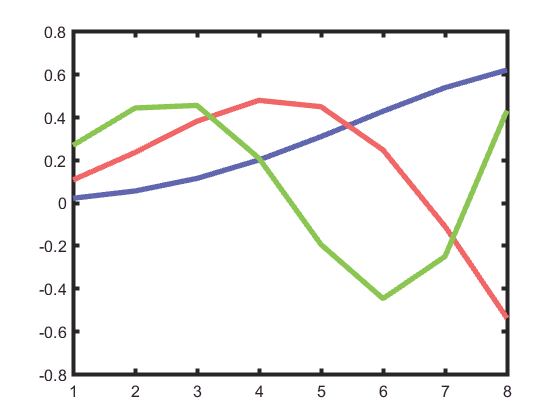

uc_all = [uc;uco];
nswimbouts = length(uc_all);
dd_all = zeros(nswimbouts);
for n = 1:nswimbouts
    for m = 1:nswimbouts
        a=[uc_all{n}(:,1)*sn(1,1),uc_all{n}(:,2)*sn(2,2),uc_all{n}(:,3)*sn(3,3)];
        b=[uc_all{m}(:,1)*sn(1,1),uc_all{m}(:,2)*sn(2,2),uc_all{m}(:,3)*sn(3,3)];
        w=100;
        dd_all(m,n)=dtw_c(a,b,w)/(length(a)*length(b));
    end
end


















%% plot

% eigenfunctions
blue = [97,103,175]/255;
red = [241,103,103]/255;
green = [138,198,81]/255;
purple = [171,78,157]/255;

figure
plot(-vn(2:9,1),'color',blue,'Linewidth',4);
hold on
plot(vn(2:9,2),'color',red,'Linewidth',4);
hold on
plot(-vn(2:9,3),'color',green,'Linewidth',4);
ax = gca;
ax.LineWidth = 3;
ax.FontSize = 12;
ylim([-0.8,0.8])

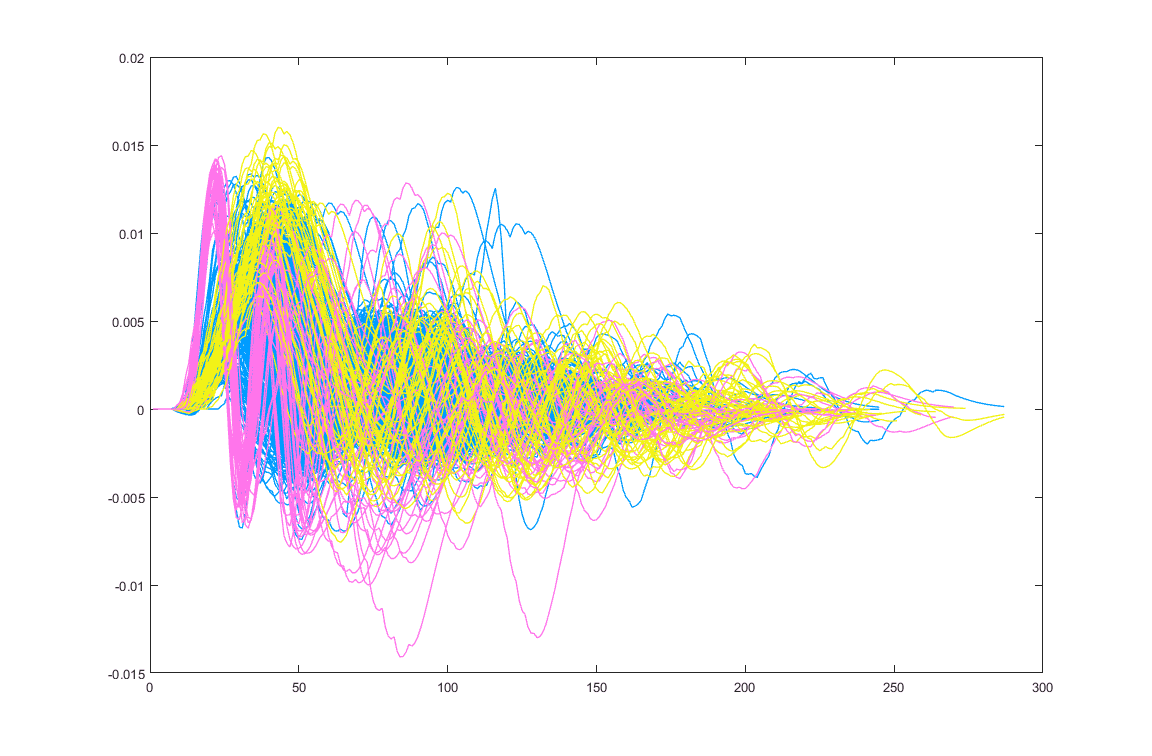


% u in 2D
bluem = [0 104 184]/255;
redm = [221,102,51]/255;
goldm = [236,171,15]/255;
purplem = [171,78,157]/255;
figure('units','normalized','position',[.1 .1 .6 .7])
for n = nswimbouts_er + 1 : nswimbouts_er + nswimbouts_fs
    plot(uc{n}(:,1),'color',[0,0.61,1],'DisplayName',sprintf('%d',n),'LineWidth',1);
    hold on
end
for n = 1:nswimbouts_er
    if swimbouts_er_n(n,5)<20
        plot(uc{n}(:,1),'color',[1,0.46,0.92],'DisplayName',sprintf('%d',n),'LineWidth',1);
        hold on
    else
        plot(uc{n}(:,1),'color',[0.95,0.95,0.09],'DisplayName',sprintf('%d',n),'LineWidth',1);
        hold on
    end
end

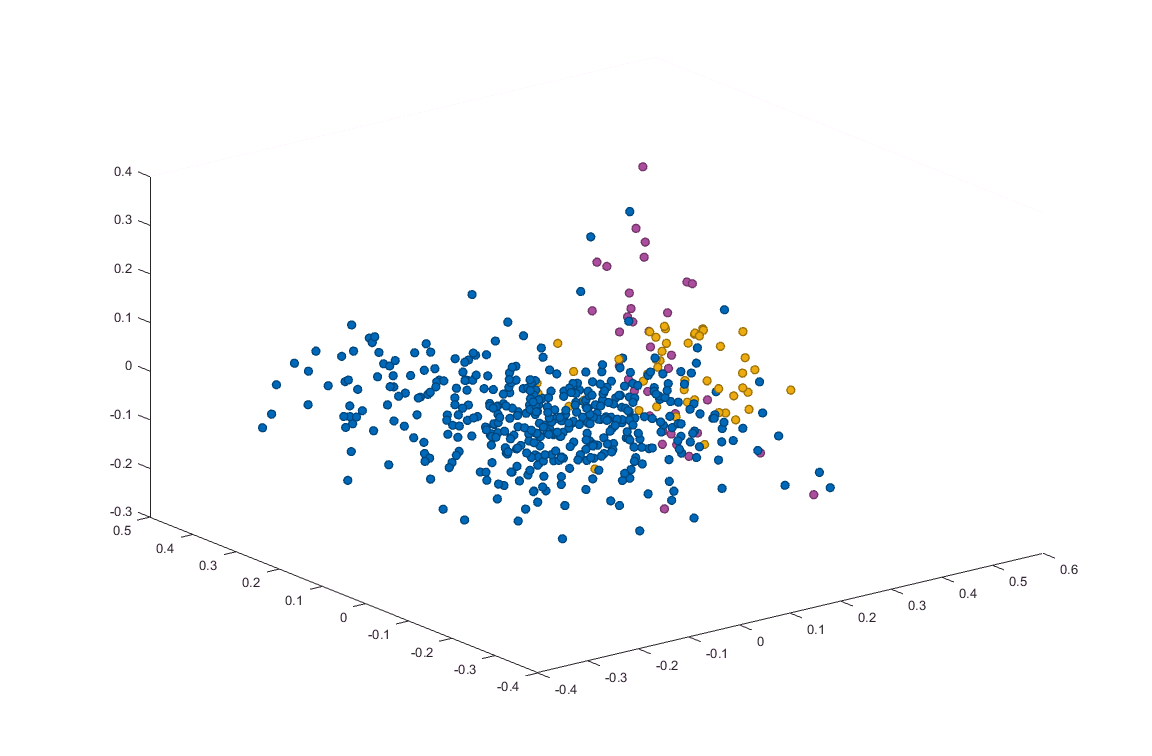


% MDS in 3D
[Y1,~] = mdscale(dd,3);
figure('units','normalized','position',[.1 .1 .6 .7])
for i = nswimbouts_er + 1 : nswimbouts_er + nswimbouts_fs
    % for i = 1:nswimbouts_fs
    plot3(Y1(i,1),Y1(i,2),Y1(i,3),'o','MarkerFaceColor',bluem,'MarkerEdgeColor',bluem/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
    hold on
end
for i = 1:nswimbouts_er
    if swimbouts_er_n(i,5)<20
        plot3(Y1(i,1),Y1(i,2),Y1(i,3),'o','MarkerFaceColor',purplem,'MarkerEdgeColor',purplem/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
        hold on
    else
        plot3(Y1(i,1),Y1(i,2),Y1(i,3),'o','MarkerFaceColor',goldm,'MarkerEdgeColor',goldm/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
        hold on
    end
end

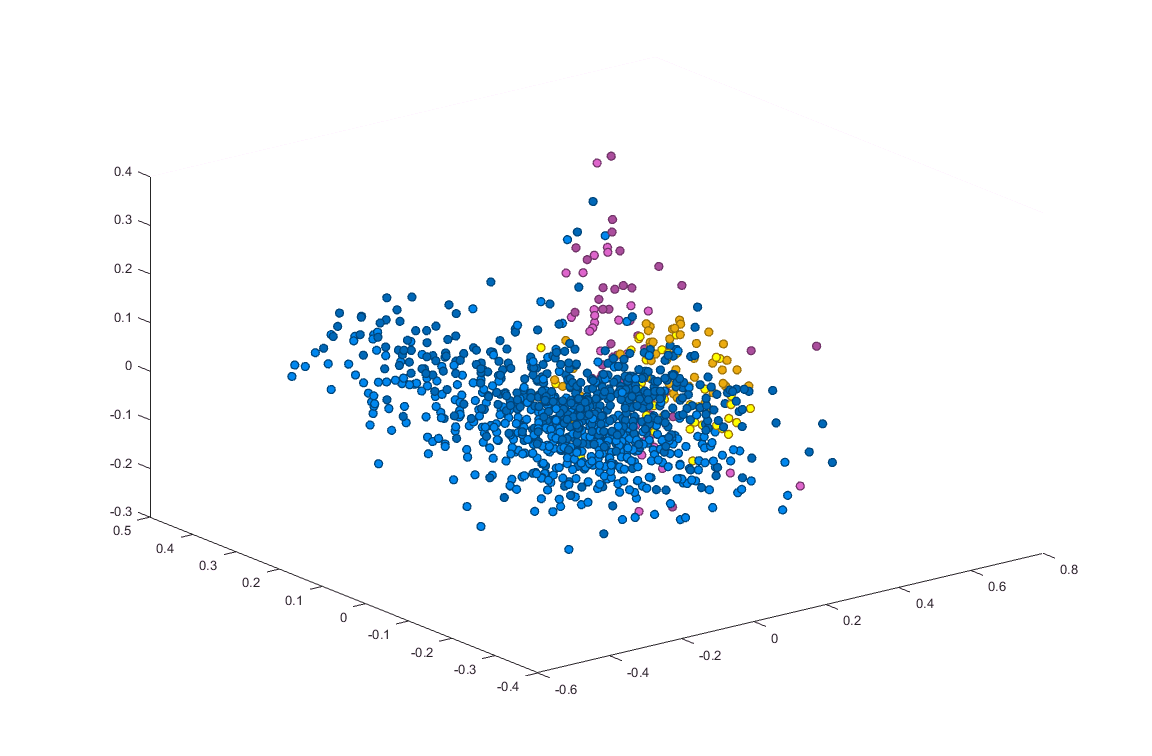



%% neuro vs original MDS

% MDS in 3D
[Y3,~] = mdscale(dd_all,3);
nswimbouts = 523;

figure('units','normalized','position',[.1 .1 .6 .7])
for i = nswimbouts_er + 1 : nswimbouts_er + nswimbouts_fs
    % for i = 1:nswimbouts_fs
    plot3(Y3(i,1),Y3(i,2),Y3(i,3),'o','MarkerFaceColor',bluem,'MarkerEdgeColor',bluem/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
    hold on
end
for i = 1:nswimbouts_er
    if swimbouts_er_n(i,5)<20
        plot3(Y3(i,1),Y3(i,2),Y3(i,3),'o','MarkerFaceColor',purplem,'MarkerEdgeColor',purplem/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
        hold on
    else
        plot3(Y3(i,1),Y3(i,2),Y3(i,3),'o','MarkerFaceColor',goldm,'MarkerEdgeColor',goldm/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
        hold on
    end
end

for i = nswimbouts + nswimbouts_er + 1 : nswimbouts*2
    % for i = 1:nswimbouts_fs
    plot3(Y3(i,1),Y3(i,2),Y3(i,3),'o','MarkerFaceColor',bluem*1.3,'MarkerEdgeColor',bluem/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
    hold on
end
for i = nswimbouts + 1 : nswimbouts + nswimbouts_er
    if swimbouts_er_n(i-nswimbouts,5)<20
        plot3(Y3(i,1),Y3(i,2),Y3(i,3),'o','MarkerFaceColor',purplem*1.3,'MarkerEdgeColor',purplem/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
        hold on
    else
        plot3(Y3(i,1),Y3(i,2),Y3(i,3),'o','MarkerFaceColor',[1,1,0],'MarkerEdgeColor',goldm/1.5,'MarkerSize',6,'DisplayName',sprintf('%d',i),'LineWidth',1);
        hold on
    end
end